%Clearing Workspace
close all;
clear all;
clc;

%Setting up number of bits to transmit
nBits = 10000000;
%Modulation Index
M = 2;

%SNR Values and related calculations
SNRdB = 1:10;
nSNR = length(SNRdB);
SNR = 10.^(SNRdB/10);
noiseAmp = 1./SNR;
sigma = sqrt(noiseAmp/2);

%Symbols allowed
symbolSpace = [1 -1];
symBinRepresentation = ['0'; '1'];

%Theoretical BER values
ThBER = exp(-SNR)/2;

%Defining container for storing simulated BER values
SimBER = zeros(nSNR, 1);

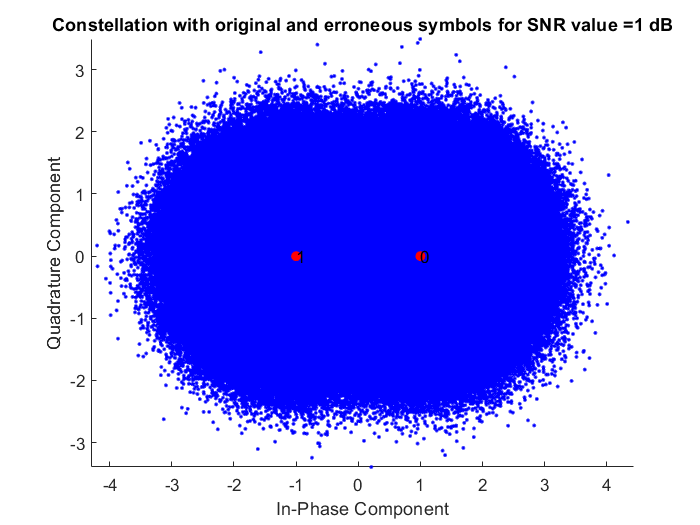

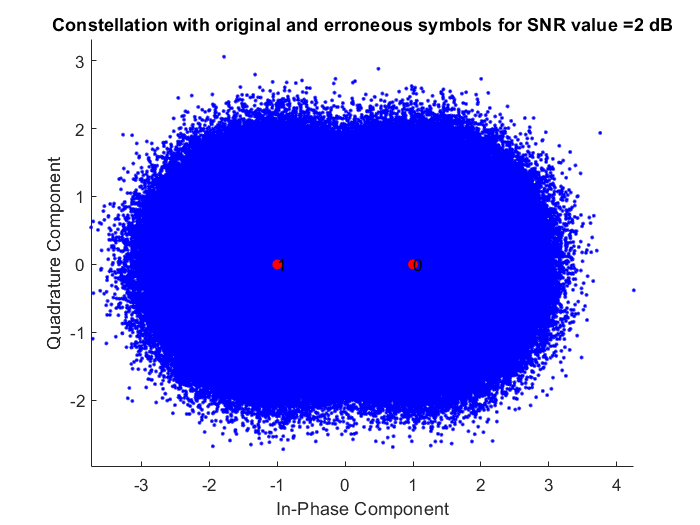

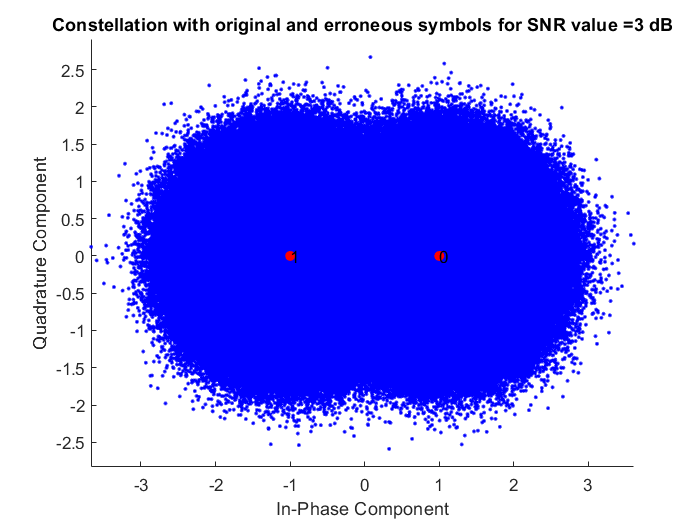

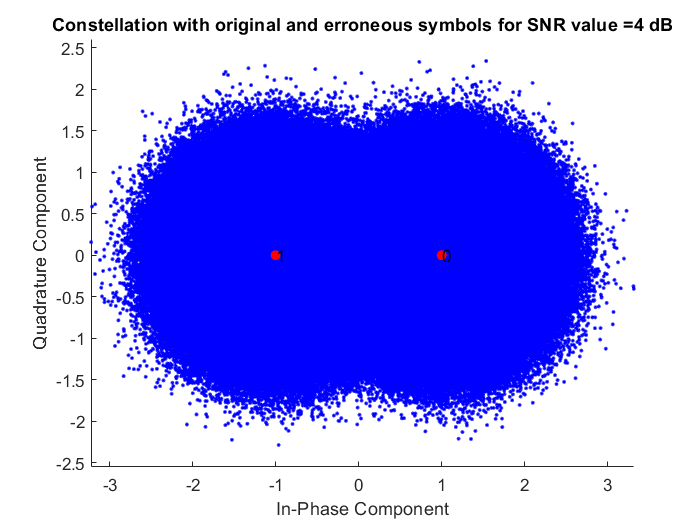

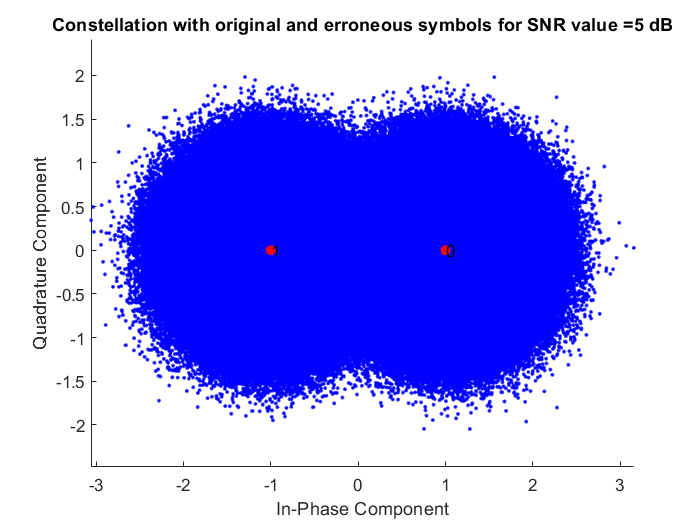

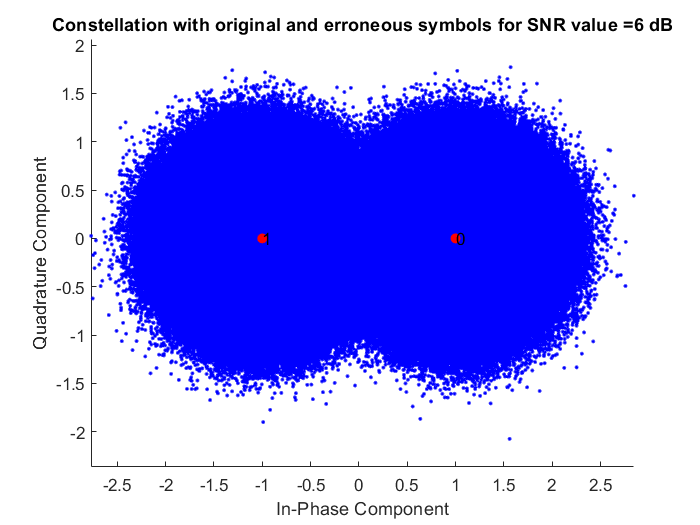

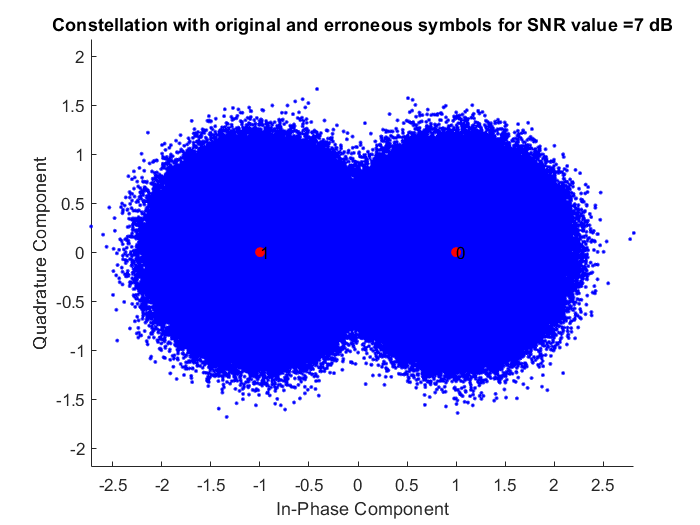

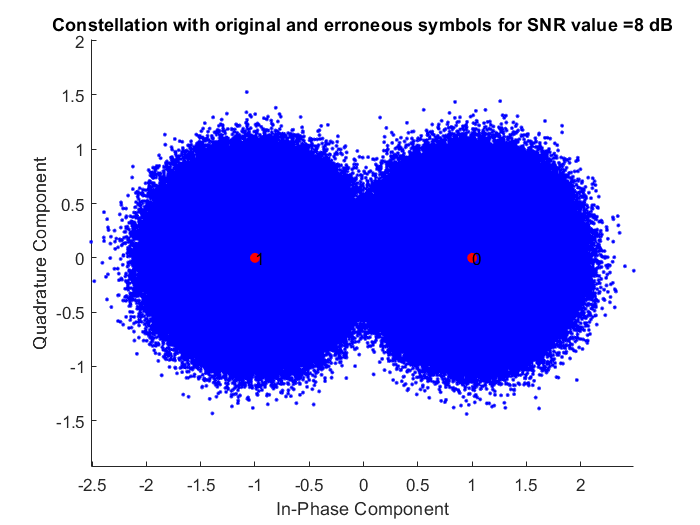

%Loop for simulation
for SNRindex = 1:nSNR
    
    %Generating random bits
    inBinSig = randi([0 1], nBits, 1);
    
    %Obtaining modulated signal using created DBPSKmodulator function
    modSig = DBPSKmodulator(inBinSig);
    
    %AWGN noise addition to modulated signal
    channelSig = modSig + sigma(SNRindex)*(randn(nBits + 1, 1) + 1i*randn(nBits + 1, 1));
    
    %Plotting constellation diagrams
    figure(SNRindex);
    scatter(real(channelSig), imag(channelSig), 'b.');
    hold on;
    scatter(real(symbolSpace), imag(symbolSpace), 'red', 'filled');
    for symIndex = 1:M
        text(real(symbolSpace(symIndex)), imag(symbolSpace(symIndex)), symBinRepresentation(symIndex));
    end
    hold off;
    xlabel('In-Phase Component');
    ylabel('Quadrature Component');
    plotTitle = strcat('Constellation with original and erroneous symbols for SNR value =', num2str(SNRdB(SNRindex)), ' dB');
    title(plotTitle);
    axis equal;
    
    %Obtaning demodulated signal using created DBPSKdemodulator function
    outBinSig = DBPSKdemodulator(channelSig);
    
    %Calculating and storing Simulation BER values
    SimBER(SNRindex) = sum(inBinSig ~= outBinSig)/nBits;
    
end

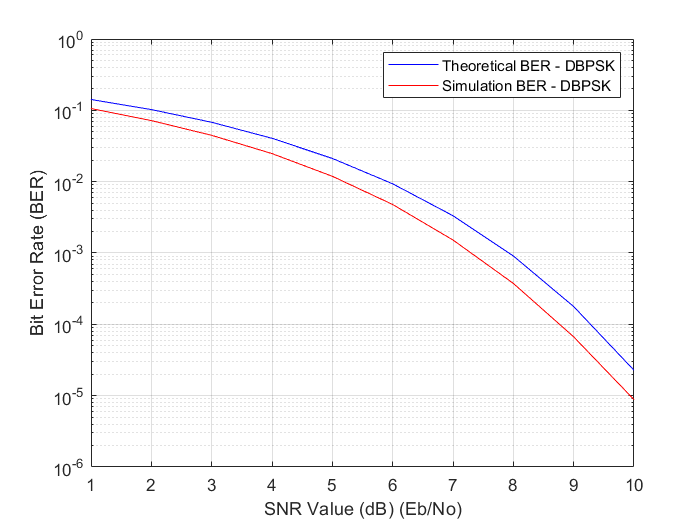

%Plotting Simulated BER vs Theoretical BER
figure(SNRindex+1);
semilogy(SNRdB, ThBER, 'blue');
hold on;
semilogy(SNRdB, SimBER, 'red');
hold off;
grid on;
xlabel('SNR Value (dB) (Eb/No)');
ylabel('Bit Error Rate (BER)');
legend('Theoretical BER - DBPSK', 'Simulation BER - DBPSK');